# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda SOR

**ĆWICZENIE 1**

Poniżej przedstawiono implementację metody SOR z różnymi współczynnikami *ω* zapisanej w postaci macierzowej dla różnych wartości omega:

Promień spektralny macierzy M: 0.80


Promień spektralny macierzy M: 0.70


Promień spektralny macierzy M: 0.60


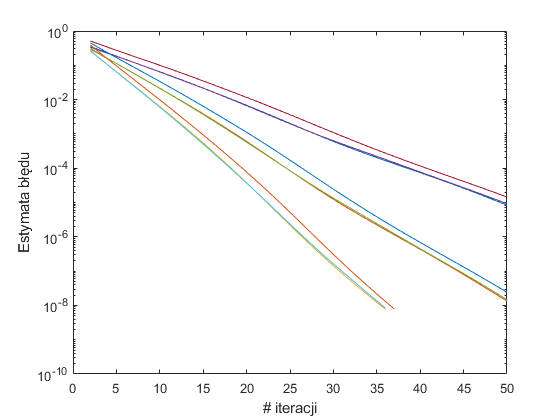

%Czyszczenie
clear all;clc;

% Najpierw zdefiniujmy przykładowy ukłąd równań:
A=wilkinson(5)+10*eye(5);
b=sum(A,2);

omegaVector = [1.8 1.7 1.6];

x_dokl=ones(5,1);

%Przyjęcie parametrów dla algorytmu iteracyjengo 
    
%-> punkt startowy - losowy
x0=rand(numel(b),1);
    
%-> wymagana dokłaność
delta0 = 1e-8;
    
%-> maksymalna ilość iteracji
i_max = 50;
    
% Dokonajmy teraz rozkłądu macierzy A wg schematu metody SOR
% uzyskując macierz M i wektor w
D=diag(diag(A));
L=tril(A)-D;
U=triu(A)-D;

%Implementacja metody SOR

n=[];     %wektor numerów iteracji do rysowania
for omega=omegaVector
    
    M_omega=inv(D+omega*L)*((1-omega)*D-omega*U);   % macierz M
    w_omega=omega*inv(D+omega*L)*b;                 % wektor w
    
    spectrumM = abs(max(eig(M_omega)));
    
    x=x0;
    err=[];i=1;n=[];
    err(1)=norm(x-x_dokl)/norm(x_dokl);             % wektor błędu
    while ( (err(end)>=delta0) & (i<i_max) )
      x=M_omega*x+w_omega; 
      err(i)=norm(x-x_dokl)/norm(x_dokl); 
      i=i+1;n=[n i];
    end 
    
    %Rysowanie błędu
    %hold off;
    fprintf("Promień spektralny macierzy M: %0.2f\n", spectrumM);
    semilogy(n,err); hold on; xlabel("# iteracji");ylabel("Estymata błędu");
end

**ĆWICZENIE 2**

Uniwersalny sposób doboru parametru $\omega$ nie jest znany. Wiadomo jednak, że:

- Aby metoda SOR była zbieżna parametr ωmusi przyjmować wartość z przedziału (0,2)

- Jeżeli macierz ***A*** jest symetryczna i dodatnio określona, to metoda ta jest zbieżna dla dowolnej wartości ω∈(0,2) - ale nie wieadomo która wartość jest optymalna

- Jeżeli macierz ***A*** jest symetryczna, dodatnio określona i ma własność A wartość optymalna jest równa:

\

gdzie  $\lambda_{\max }$  jest wartością własną macierzy ${\mathit{\mathbf{D}}}^{-1} \left(\mathit{\mathbf{L}}+\mathit{\mathbf{U}}\right)$ 